data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';
neuro_root_dir = 'neurodata/ac1/';
movie_root_dir = 'movie_frames/movie000_000.images/';
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);
load(neuro_str);

load_img = strcat(data_root_dir, movie_root_dir, current_movie);

%if ~strcmp(str1, str2)
%    disp('Strings are different');
%end

imread(load_img);

## Total Number of Conditions

pepANA.no_conditions

## Arrival Times for electrodes in pepANA.elec_list

pepANA.listOfResults{1}.repeat{1}.data{13}

ans = 120

## Detected Waveforms at that time (48 samples of waveform snippets) (contains spikes and noise bc of low threshold) (1.6ms sampled at 30kHz at int8 precision)

pepANA.listOfResults{1}.repeat{1}.data{1}{2}

ans = 1×2 cell array
    {[0.3537 0.4543 0.6036 0.6780 1.0123 1.1758 1.1779 1.1914 1.4126 1.4425 1.5338 1.6866 1.9662 2.5828 2.9451 3.3012 3.7744 3.9322 4.0201 4.6491 4.6791 4.7038 4.7153 4.7283 4.7530 4.9453 5.0114 5.0702 5.1571 5.2284 5.2450 5.2530 5.2793 5.3124 5.4489 5.4555 5.5446 5.6120 5.6444 5.9074 5.9447 6.0529 6.1861 6.4447 6.4658 6.4674 6.5947 6.6364 6.7368 6.7395 6.7992 7.1861 7.2076 7.2251 7.4116 7.4175 7.4342 7.4409 7.7366 7.7383 7.7427 7.7602 7.7752 7.9908 7.9988 8.0911 8.1284 8.2868 8.2950 8.3093 8.6980 8.7073 8.7739 8.9820 8.9861 9.3858 9.4068 9.4084 9.4132 9.4214 9.4284 9.4361 9.4736 9.4948 11.3779 11.5023 11.5521 11.5728 12.3103 12.4606 12.6606 12.7947 12.7983 12.9645 13.7019 13.7352 13.8687 14.5684 14.5775 14.6017 14.6351 14.6436 14.8638 14.8761 15.2851 15.3940 15.4686 15.4931 15.7483 16.3330 16.3440 16.8394 17.2726 17.2844 17.3010 17.4568 17.4682 17.5766 17.7683 18.4053 18.7387 19.0184 19.0555 19.1096 19.2100 19.6099 19.8890 19.8935 19.9430 19.9933 20.5885 22.0093 2

(size(pepANA.listOfResults{1}.repeat{1}.data{1}{1}, 2) / 30000) * 1000

ans = 48×573 int8 matrix
     0    -6    -2     3    -3    -8     3     0    10    -7    -2     4    -6     3    -5     8    -8    -8    -3   -11     4   -15    -3    -8     9     2    -6    -4    -8    -1    -7     0    -9    10    -6     5    -7    -9    16    -3    20    -1   -11     9     0    -9    -3     5    -5   -16
    -1    -3    -2     2    -1     1    -3    -3    -2    -4    -3     7    -7     1    -7     5    -3    -9     1    -5     2   -18    -6   -16    -2     5   -10    -1    -7     3   -10    -1    -9     0     0     7   -13   -10     4    -7    17    -3   -17    -2     4   -14    -9     9    -8   -19
     3    -3    -2     1    -1     8    -3    -5    -8    -2     4     6    -6    -5    -7     2    -4     0     2    -1     1   -13    -4   -14    -7     4   -12    -8     1     3    -6    -5    -7    -7     2     5   -14    -5     3     5    18     2   -12    -7     7    -7   -12     4    -7   -11
     1    -3    -3     1    -3     6     1    -6    -2    -3     1     3

## Electrodes

pepANA.elec_list

ans = 19.1000

## Examining Waveforms

q = pepANA.listOfResults{1}.repeat{1}.data{13}{2};

ans =      5     6    10    13    15    22    23    26    38    46    47    54    55    73    78    85


% size(q(1, :));
% one_waveform = q(1, :);
% plot(one_waveform)

% fig_multiple_spikes_electrode13 = figure("Name", "Channel 13 Electrode");
% ax_multi_spikes_channel13 = axes("Parent", fig_multiple_spikes_electrode13);
% plot(ax_multi_spikes_channel13, q);

## SVD of Waveforms

function mean_detected_signal = analyzeWaveform(condition, electrode, verbose)
    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    if nargin < 3
        verbose = false;
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    
    % Extract waveform
    waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

    % Ensure waveform is in double precision
    waveform = double(waveform);

    % Perform SVD
    [~, ~, v] = svd(waveform);

    % Plot first two principal components
    if verbose
        fig1 = figure('Name', 'Original Waveforms', 'Position', [100, 100, 800, 600]);
        ax1 = axes('Parent', fig1);
        plot(ax1, v(:, 1), v(:, 2), '.', 'MarkerSize', 10);
        hold(ax1, 'on');
        plot(ax1, 0, 0, 'r.', 'MarkerSize', 25);
        xlabel(ax1, '1st Principal Component');
        ylabel(ax1, '2nd Principal Component');
        title(ax1, sprintf('SVD Projection: Condition %d, Electrode %d', condition, electrode));
        grid(ax1, 'on');
    end
        

    idx = kmeans(double(waveform'),2); %% cluster waveforms in 2 classes using k-means
    idx1 = find(idx==1); 
    idx2 = find(idx==2);

    % Determine which cluster is likely the signal
    mean1 = mean(waveform(:, idx1), 2);
    mean2 = mean(waveform(:, idx2), 2);

    total_amplitude1 = sum(abs(mean1));
    total_amplitude2 = sum(abs(mean2));

    if total_amplitude1 > total_amplitude2
        signal_idx = idx1;
        noise_idx = idx2;
    else
        signal_idx = idx2;
        noise_idx = idx1;
    end

    if verbose
        fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");
        ax3_1 = subplot(1, 2, 1, "Parent", fig2);
        plot(ax3_1, v(noise_idx, 1), v(noise_idx, 2), 'b.', 'markersize',10); 
        hold on;
        plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
        plot(ax3_1, v(signal_idx, 1), v(signal_idx, 2), 'g.', 'markersize', 10);
    
        ax3_2 = subplot(1, 2, 2, "Parent", fig2);
        errorbar(ax3_2, 1:size(waveform,1), mean(double(waveform(:, signal_idx)'),1), std(double(waveform(:, signal_idx)'),[],1), 'g'); 
        hold on;
        errorbar(ax3_2, 1:size(waveform,1), mean(double(waveform(:, noise_idx)'),1), std(double(waveform(:, noise_idx)'),[],1), 'b');
    
        xlim([0 49])
    end
    mean_detected_signal = mean(double(waveform(:, signal_idx)'),1);
end

data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';
neuro_root_dir = 'neurodata/ac1/';
movie_root_dir = 'movie_frames/movie000_000.images/';
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);
load(neuro_str);

condition = 1

condition = 1

electrode = 1

electrode = 1

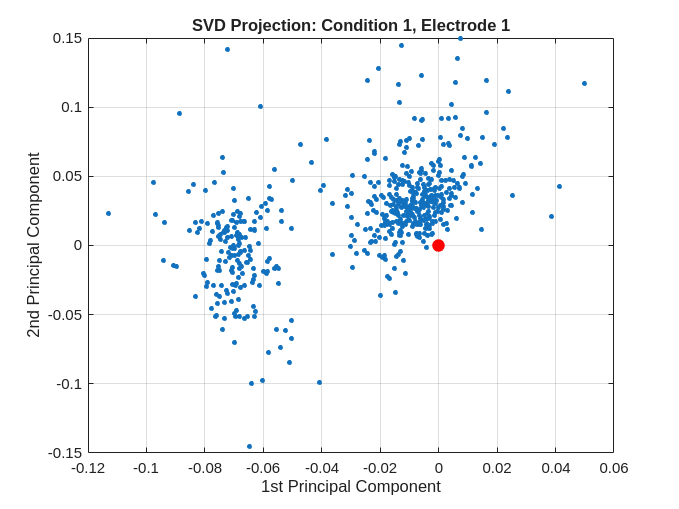

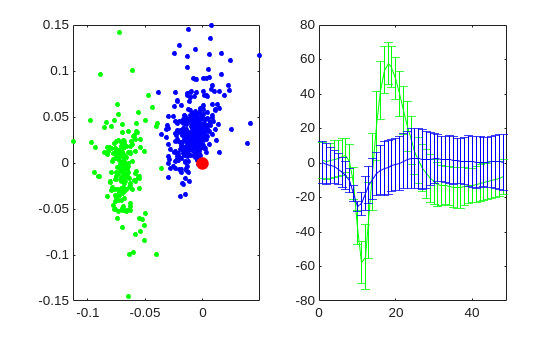

signal = analyzeWaveform(condition, electrode, true);

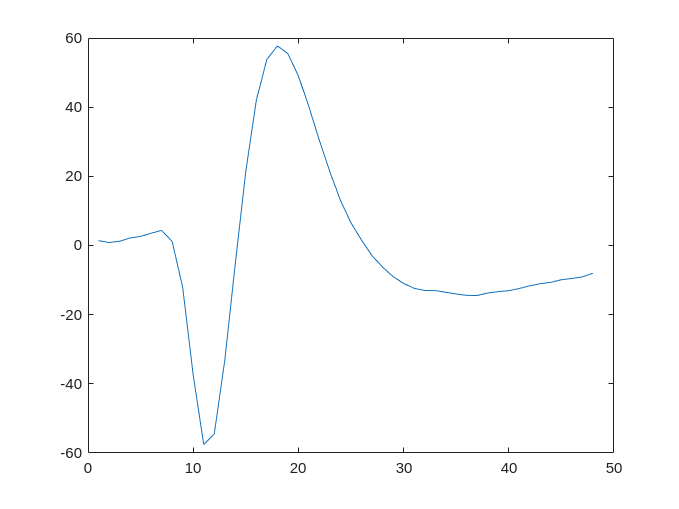


% Plotting the detected spike waveform only
fig0 = figure('Name', 'Detected Waveform', 'Position', [100, 100, 800, 600]);
ax0 = axes('Parent', fig0);
plot(ax0, signal)

signal =     1.4062    0.8698    1.2292    2.1823    2.6302    3.5521    4.3698    1.1562  -12.0729  -37.4531  -57.5156  -54.5469  -33.2396   -5.2969   21.4583   41.9948   53.7865   57.7031   55.4844   49.0469   40.0833   30.3333   21.2188   13.0312    6.5417    1.5729   -2.9583   -6.2188   -9.0052  -10.9792  -12.3698  -13.0156  -13.0417  -13.5104  -14.0208  -14.4271  -14.4583  -13.7396  -13.3229  -13.0677  -12.4167  -11.6562  -11.0260  -10.6510   -9.8958   -9.5312   -9.0833   -7.9844


signal =     1.6667    1.0505    1.2222    0.5152   -0.8586   -1.0303   -1.4545   -4.8283  -15.3434  -32.4343  -42.6667  -34.8485  -13.6364   10.3838   28.1616   37.3636   40.6667   38.7778   33.0606   26.6465   20.0808   13.3939    8.4040    4.3030    0.7677   -1.8788   -4.0909   -5.5455   -5.4949   -6.1313   -6.5657   -6.2828   -6.9394   -7.5556   -8.1515   -7.9495   -7.7677   -7.1313   -7.1212   -6.6263   -6.4242   -6.5354   -6.6465   -6.7677   -6.1919   -5.9697   -4.9293   -4.7374


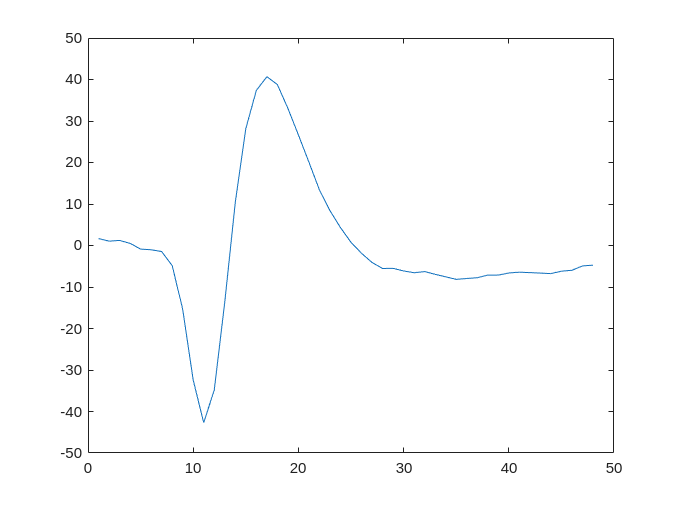

signal =     0.5000   -0.3217   -1.4304   -2.0043   -2.7587   -3.9935   -5.4196   -8.3326  -16.2370  -25.7457  -26.0630  -19.0478  -10.2435   -2.1174    5.1065   11.6804   17.1022   20.7370   23.1022   24.0848   23.5652   21.6848   19.2348   16.7109   13.8196   10.7674    7.7109    4.6391    1.5587   -0.8696   -2.6065   -3.9109   -5.3804   -6.5130   -7.0065   -7.3674   -7.7935   -8.1522   -8.3935   -8.1500   -8.1957   -8.4152   -8.1696   -7.6870   -7.1217   -6.7587   -6.5348   -5.9543


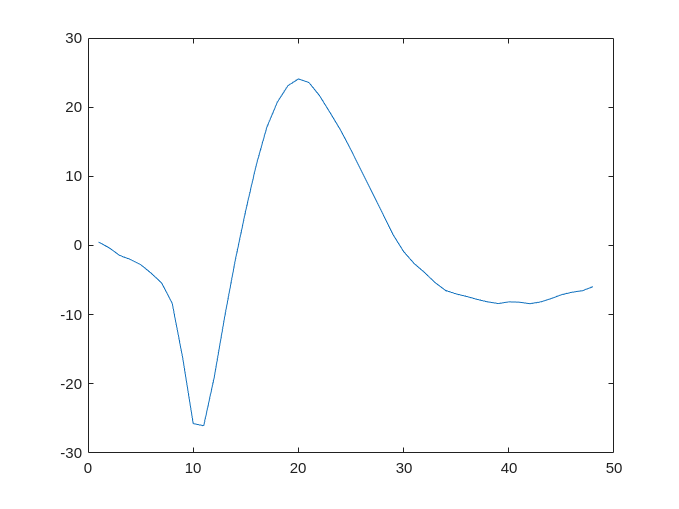

signal =     0.0476   -0.2500    0.1190    0.2738   -0.1310   -0.7738   -2.8571   -7.3690  -17.8690  -30.2619  -31.2262  -21.2738   -7.4286    4.9167   15.2024   22.3571   25.6310   26.3333   23.6786   20.4762   17.5476   14.1905   10.7500    7.4286    5.1905    3.4524    1.1548   -0.9881   -1.8214   -3.1905   -4.9762   -5.9762   -6.3214   -5.9524   -6.1190   -6.3690   -6.0595   -6.1310   -6.0476   -5.8333   -5.9762   -5.2381   -4.1548   -3.7143   -3.0833   -1.7143   -1.0952   -0.7857


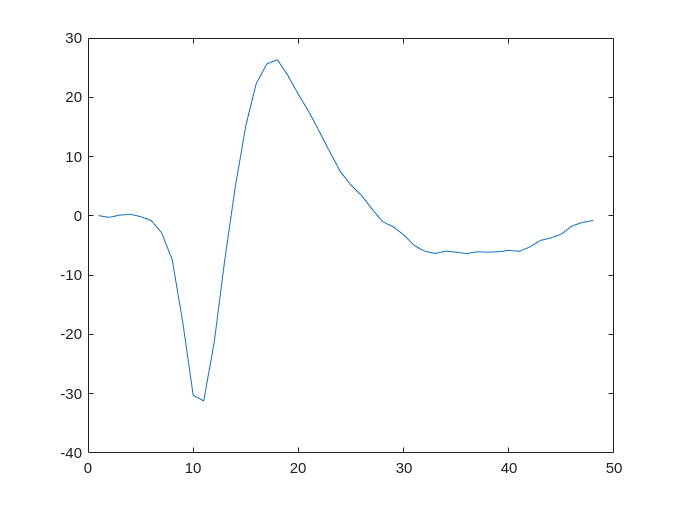

signal =     0.5521    0.3606    0.0056   -0.0563    0.0507    0.2169   -0.0479   -3.6958  -16.1352  -42.7211  -66.7493  -63.0451  -37.9324   -7.4789   21.0310   44.7352   61.0169   68.1268   65.9972   57.8197   47.0817   36.0423   25.9239   16.8338    9.6366    3.6085   -0.6000   -4.4113   -7.0507   -8.9296  -10.4901  -12.1042  -12.7831  -13.3296  -14.0225  -14.4817  -14.3183  -14.3239  -13.9465  -13.0028  -12.0451  -11.8901  -11.3606  -10.5718   -9.8056   -9.3521   -9.1268   -9.0930


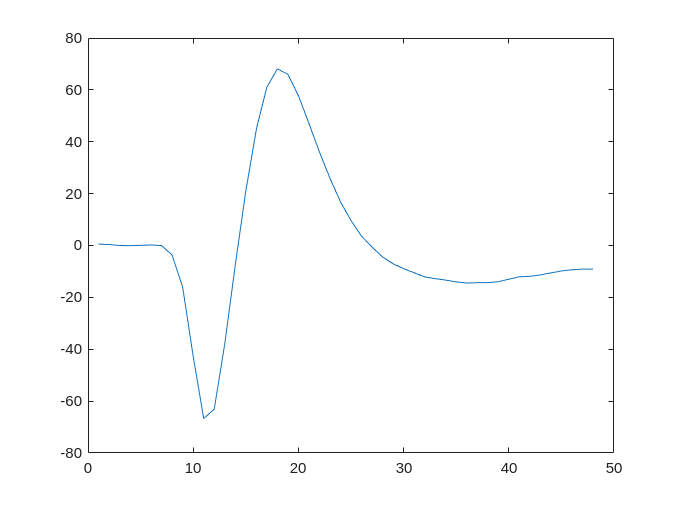

signal =     4.3438    3.5625    1.4062    0.4375    1.2812    2.8438    3.3125   -3.1875  -20.4375  -48.7500  -72.8438  -82.0938  -72.5625  -45.6250  -13.4688   12.8750   31.8750   46.3125   54.5938   59.1875   61.0625   62.4375   60.6875   58.7500   56.7188   52.8750   48.6562   43.5000   38.1250   33.4062   27.7188   22.1250   15.5000    9.8125    4.3750   -2.0312   -8.1875  -12.6875  -16.1250  -18.1875  -19.0312  -20.6875  -22.7188  -24.9688  -26.7188  -27.6875  -26.9375  -27.3438


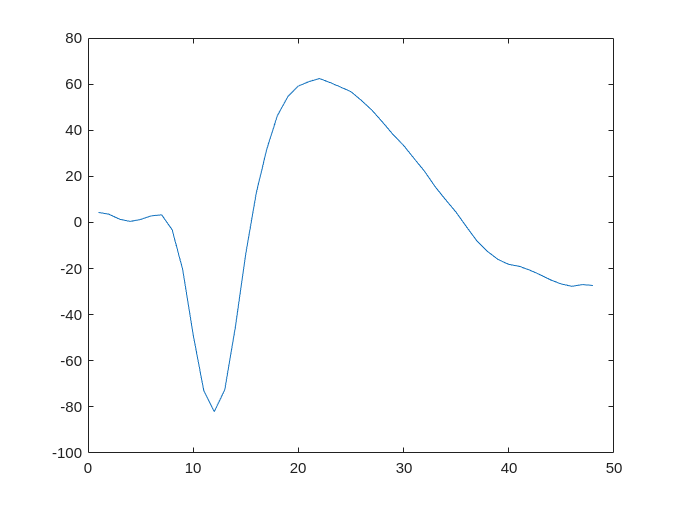

signal =    -0.2381   -0.3598    0.0159    0.0212   -0.8519   -1.3333   -2.2698   -6.2540  -14.5873  -23.8466  -24.0476  -17.3651   -9.7619   -1.6508    7.4974   16.4762   22.7937   25.2169   24.5344   21.4021   17.3439   12.7037    8.1481    4.2593    0.2910   -3.0053   -4.5820   -5.7672   -6.6032   -6.8677   -7.1587   -7.3175   -7.2169   -6.7989   -6.2487   -5.9524   -5.5661   -5.0529   -4.4868   -3.7143   -2.9153   -3.2434   -3.7778   -3.3968   -2.3862   -1.4497   -1.4286   -1.5344


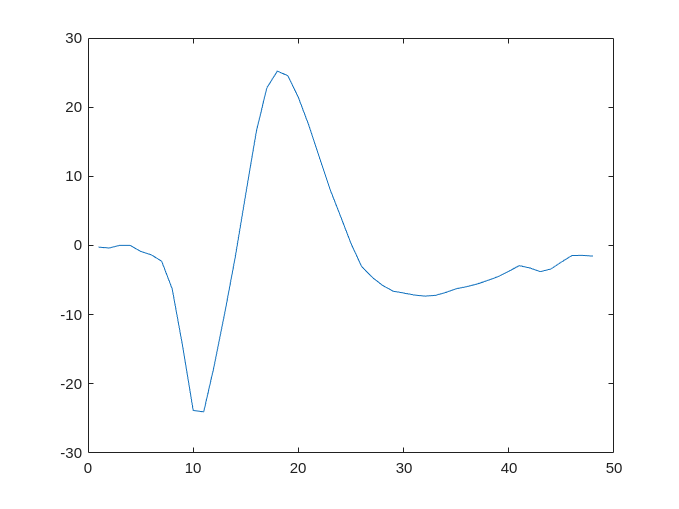

signal =     0.8723    1.2979    1.6383    1.6383    0.2553   -1.2766   -3.1277  -10.8723  -25.0000  -41.7021  -58.0851  -64.3191  -48.8936  -17.2128   14.2128   37.5532   52.8085   60.9362   63.3617   61.1489   57.1489   51.4468   46.8511   40.9149   32.6809   24.8085   17.0213    8.5957    0.6809   -5.6383   -9.8298  -12.7234  -17.1489  -19.2766  -20.3404  -21.0851  -22.5319  -23.4894  -23.4043  -23.0000  -21.8936  -23.0638  -22.9787  -20.2340  -18.1702  -16.9574  -16.4255  -15.2128


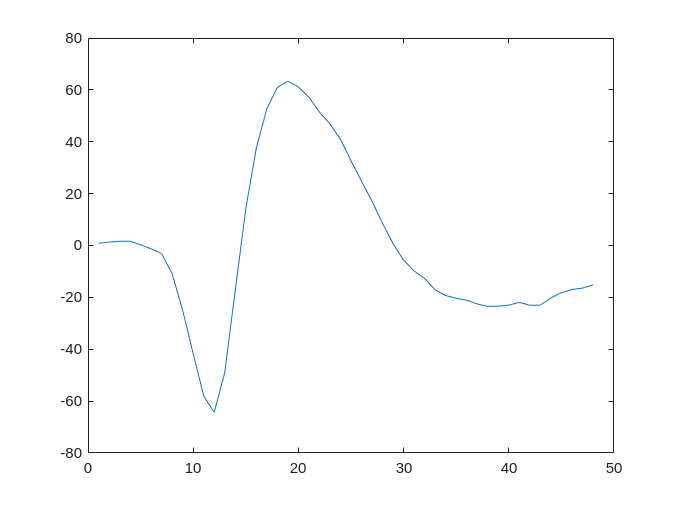

signal =     2.0750    1.1875   -0.2500   -2.1125   -3.6250   -5.3125   -8.0750  -12.8750  -23.8750  -36.7000  -41.2500  -38.1125  -31.6375  -23.4250  -11.4750    1.7750   13.8125   23.9125   30.9750   34.0500   35.3375   34.5125   32.3000   29.0125   25.6750   21.6875   18.7750   15.9875   12.2000    9.2250    7.2500    5.1500    3.0625    1.0625   -1.1250   -2.3250   -3.7375   -5.3500   -6.8000   -8.7625   -9.4250   -9.4125   -9.8000  -11.3375  -12.9500  -13.1125  -11.7000  -11.3875


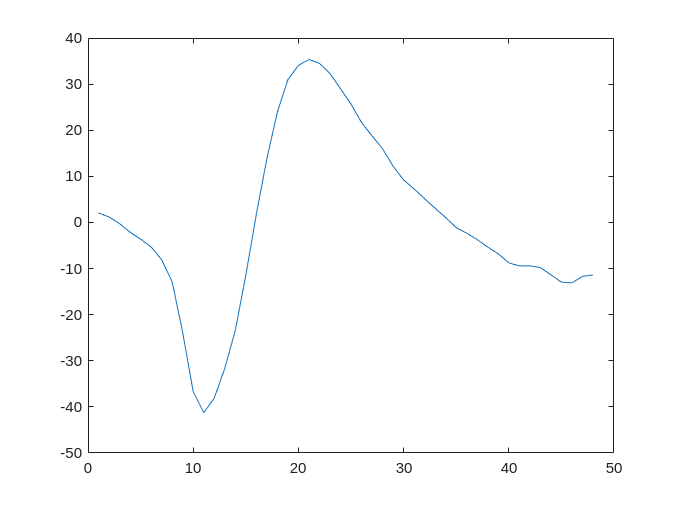

signal =     0.8868    0.4340   -0.1572   -0.4465   -0.8616   -0.8365   -0.9686   -4.5346  -14.3711  -27.4780  -33.8868  -31.1950  -23.8113  -14.7862   -4.8302    3.5849   10.4340   15.7107   19.6981   21.7736   22.9937   23.4906   23.5660   22.8239   21.7421   20.3585   18.4969   16.9686   15.5220   12.9874    9.4843    7.3019    5.2704    3.4591    1.4465   -0.7610   -2.9057   -4.2264   -5.0629   -6.1635   -7.6101   -8.5283   -9.3459   -9.9057  -10.4528  -10.6981  -10.9245  -11.5535


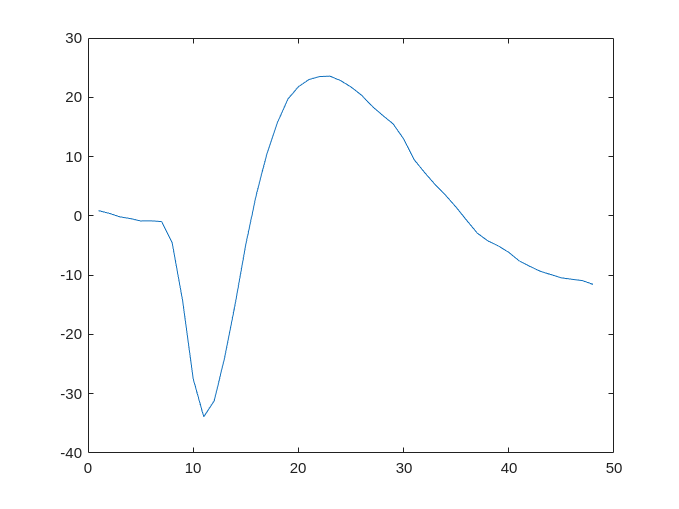

signal =     2.4074    2.4630    0.6296   -1.6667   -1.9444   -1.9815   -3.3519   -6.6852  -17.3148  -33.1852  -40.8519  -32.9815  -15.7593    0.0185   11.5000   21.1111   26.4444   28.0370   27.6852   26.3148   23.0556   19.5185   16.8519   15.1111   14.0370   12.4444   11.0926    9.1111    5.8704    2.7407   -0.5185   -2.0556   -3.7037   -5.1852   -6.2963   -7.3889   -8.5185   -9.1296  -11.2963  -12.1852  -11.8519  -10.6481  -10.3148   -7.8704   -6.2778   -5.8889   -6.7037   -6.5741


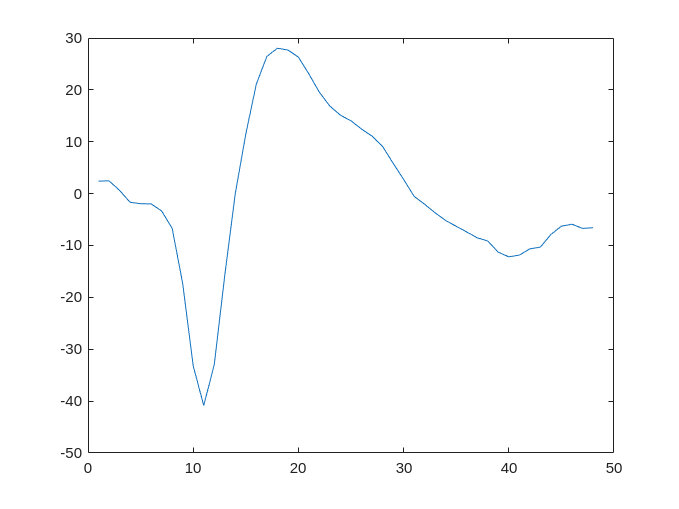

signal =     0.4000    1.0632    1.6211    1.8053    2.0947    1.8684    1.5316   -2.7421  -13.4316  -28.5211  -37.9632  -39.1526  -33.7632  -23.6000  -11.3474    1.3737   12.6211   21.4842   27.3684   30.8474   32.8526   33.4211   33.4737   32.8158   31.0737   29.1579   26.9421   23.9158   20.3474   16.7895   13.4316    9.8368    5.4474    2.1000   -0.6263   -3.5579   -6.3053   -8.8158  -10.5316  -12.3947  -13.7263  -14.1684  -15.0211  -15.9316  -15.5421  -14.9895  -14.9000  -14.2842


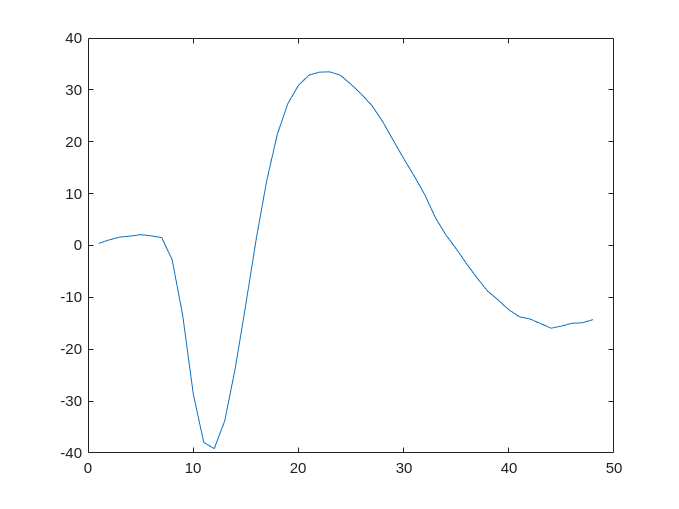

signal =    -1.5556   -2.3704   -1.0741   -0.0741   -0.4074    0.9630    3.4444    1.3333  -13.0370  -41.1111  -61.7037  -54.7778  -32.4815  -10.9630    3.4074   13.7037   20.7778   27.2963   30.4815   29.7037   31.1481   32.7778   30.8148   28.7037   27.3333   25.5926   24.4444   21.4444   16.9259   14.7778   12.9630    8.5926    2.7407   -1.5185   -3.3333   -5.1481   -8.5556  -10.8889  -11.0000  -12.2222  -15.6667  -15.9630  -14.5556  -13.3333  -13.1481  -12.5926  -11.9630  -12.2593


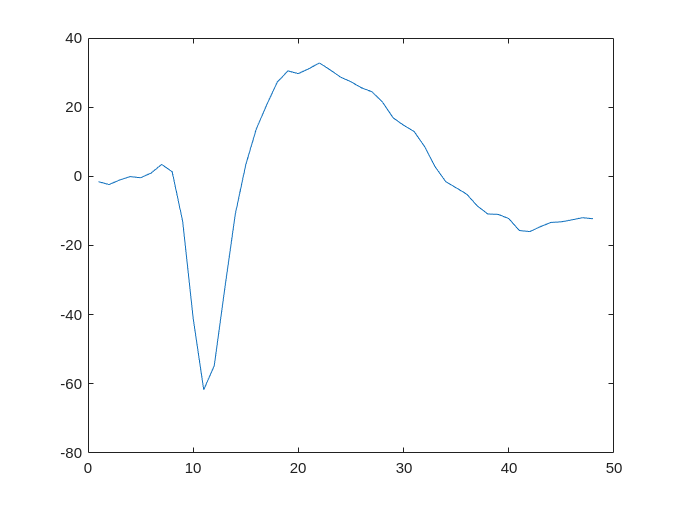

signal =     0.1031   -0.8660   -1.0206   -1.2371   -1.5361   -1.9485   -4.3196   -8.9485  -19.6082  -33.5979  -39.4742  -35.2474  -25.8866  -15.4330   -5.0515    4.5567   12.4227   18.5876   22.9897   25.3711   27.1856   28.5979   28.8144   27.9175   26.4639   25.1134   22.6907   20.0000   17.3196   14.9485   12.8144   10.7938    7.9897    5.5773    3.4742    0.4433   -2.4021   -5.0928   -6.8454   -7.6598   -8.3196   -9.1649   -9.7423  -10.4124  -11.2165  -11.7423  -11.7732  -11.4124


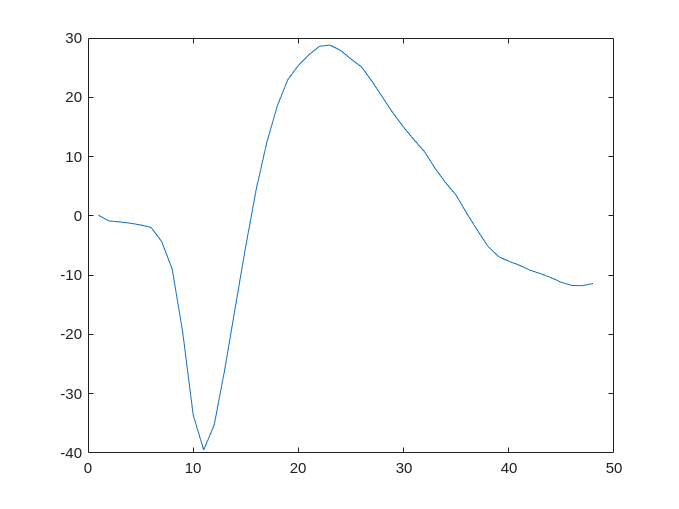

signal =     1.5772    1.9060    1.6040    0.8926    0.6644    2.2416    2.5973   -4.0470  -21.9799  -39.4228  -39.4295  -25.2215   -7.3624    9.5369   23.9128   33.9060   40.1275   40.9732   36.8859   30.9128   23.4765   16.1879    9.9933    4.0268   -0.7651   -3.5034   -5.6510   -7.9195   -9.9933  -11.0940  -11.6711  -12.3893  -12.7248  -11.7584  -10.4161   -9.6779   -8.8859   -7.6644   -7.4295   -7.0604   -6.4362   -6.5503   -6.3893   -5.8255   -5.0067   -3.9060   -3.4161   -2.7785


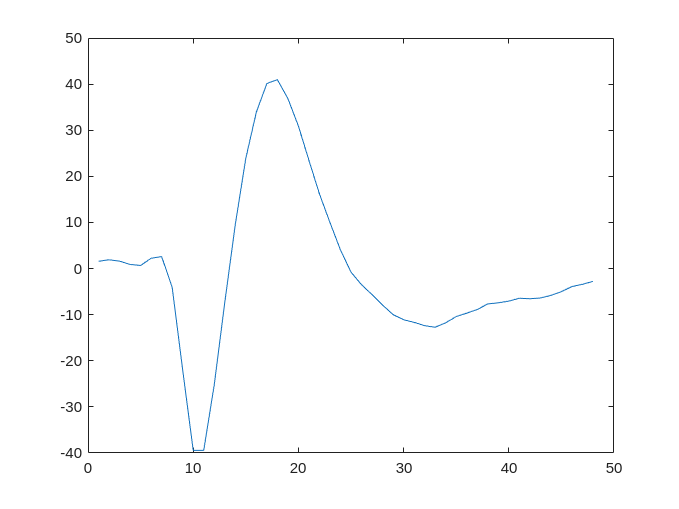

signal =    -1.0909   -1.5354   -1.6263   -1.4747   -1.2323    0.4798    1.6010   -3.6667  -19.8889  -36.7424  -36.6869  -21.9949   -3.5404   13.7879   26.1364   32.6616   33.9899   30.6970   25.6717   20.2727   14.5606    9.1515    4.3889    0.9596   -1.2980   -3.5960   -5.0303   -6.1414   -6.5253   -7.3485   -7.4343   -7.8636   -7.7424   -7.0556   -6.8030   -6.2525   -5.3788   -4.7828   -4.7071   -4.8535   -5.2121   -4.9293   -3.7980   -3.3889   -3.2020   -2.7172   -1.7424   -1.8990


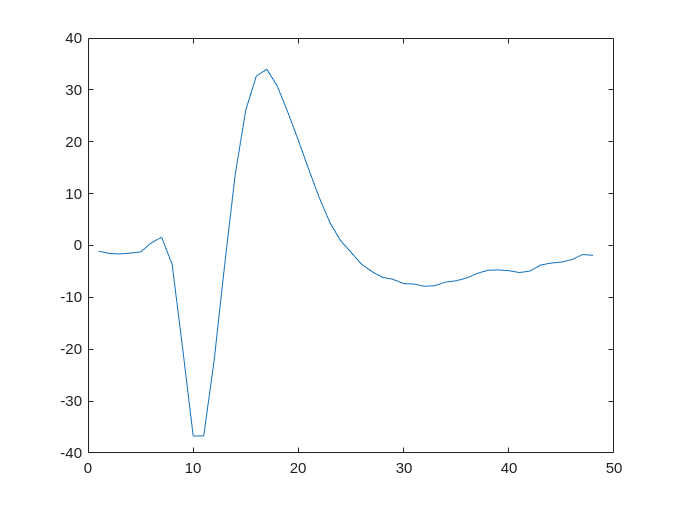

for electrode = 1:16
    signal = analyzeWaveform(condition, electrode);

    fig0 = figure('Name', 'Detected Waveform', 'Position', [100, 100, 800, 600]);
    ax0 = axes('Parent', fig0);
    plot(ax0, signal)
end



waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

[u, s, v] = svd(double(q));
fig1 = figure('Name', 'Original Waveforms', "Position", [100, 100, 800, 600]);
ax1 = axes("Parent", fig1);
plot(ax1, v(:, 1), v(:, 2), '.', 'markersize', 10);
hold on;
plot(ax1, 0,0, 'r.', 'markersize', 25);

## Classifying Waveforms with K-means clustering

fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");

idx = kmeans(double(q'),2); %% cluster waveforms in 2 classes using k-means
idx1 = find(idx==1); 
idx2 = find(idx==2);

ax3_1 = subplot(1, 2, 1, "Parent", fig2);
plot(ax3_1, v(idx1, 1), v(idx1, 2), 'b.', 'markersize',10); 
hold on;
plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
plot(ax3_1, v(idx2, 1), v(idx2, 2), 'g.', 'markersize', 10);

ax3_2 = subplot(1, 2, 2, "Parent", fig2)
errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx2)'),1), std(double(q(:, idx2)'),[],1), 'g'); 
hold on;
errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx1)'),1), std(double(q(:, idx1)'),[],1), 'b');

xlim([0 49])

% set(gcf, 'Renderer', 'painters'); % or 'opengl'

% waveform = pepANA.listOfResults{1}.repeat{1}.data{13}{2}(1, :)
% fig0 = figure("Name", "Single Waveform");
% ax0 = axes("Parent", fig0);
% plot(ax0, waveform);

% plot(ax0, pepANA.listOfResults{1}.repeat{1}.data{13}{1})

## Natural image sequences data:

% Indices of the movie frame that appeared 60ms before a spike 
c = 1 % condition
T = 3/90 % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
spk = pepANA.listOfResults{c}.repeat{1}.data{13}{1};
spk = spk - 60e-3; % frames 60 ms before a spike sample
frame_idx = floor(spk/T);
frame_idx

frame_idx(1);
n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1)

## Getting the frames

movie_id = pepANA.listOfResults{120}.values(1);
segment_id = pepANA.listOfResults{120}.values(2);

n_prefix_zeros = 3 - (floor(log10(segment_id{1})) + 1)
prefix_zeros_segment_id = sprintf('%s', repmat("0", 1, n_prefix_zeros));

% Indices of the movie frame that appeared 60ms before a spike 
c = 1 % condition
T = 3/90 % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
spk = pepANA.listOfResults{c}.repeat{1}.data{13}{1};
spk = spk - 60e-3; % frames 60 ms before a spike sample
frame_idx = floor(spk/T);

% Create the string to show the image that is the stimulus to the detected spike
n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1);
prefix_zeros_frame_idx = sprintf('%s', repmat("0", 1, n_prefix_frame_zeros))
movie_image_string = "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + "_" + prefix_zeros_frame_idx + int2str(frame_idx(1)) + ".jpeg"
movie_image_dir = data_root_dir + "movie_frames/" + "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + ".images/"
image_path = strcat(movie_image_dir, movie_image_string);
img = imread(image_path);
imshow(img)